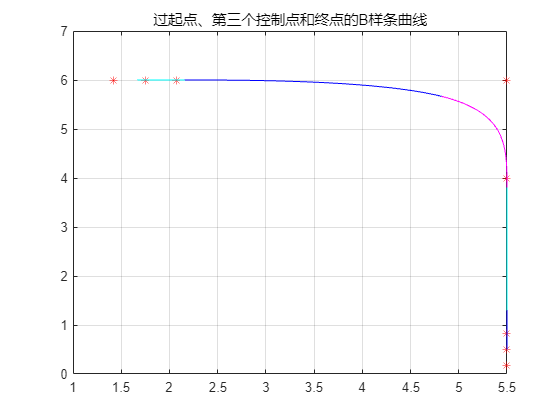

%设定3个控制点C=[C1 C2 C3]
C=[ 5.5 5.5 5.5 1.75 
     0.5  4.0  6.0  6.0];
V1=[0;1];       %起点C1出发速度方向V1
V2=[1;0];       %到终点C5速度方向V2
%V3=[-1;0];      %第三个控制点C3的速度方向V3
V4=[0,0];
V5=[1,1];
L=0.65/2;      %L为小车长度的一半
RC=[C(:,1)-V1*L,C(:,1),C(:,1)+V1*L,C(:,2),C(:,3),C(:,4)-V2*L,C(:,4),C(:,4)+V2*L];
N=length(RC);   %控制点扩充后的控制点数目
s=0:0.01:1;     %归一化路程
%四个样条函数f1(s)、f2(s)、f3(s)、f4(s)
f1s=(1-s).^3/6; 
f2s=(3*s.^3-6*s.^2+4)/6;
f3s=(-3*s.^3+3*s.^2+3*s+1)/6;
f4s=s.^3/6;
%绘制过起点、第三个控制点和终点的B样条曲线
figure(1);mycolor='mbc';
plot(RC(1,:),RC(2,:),'r*');
hold on;for i=1:N-3
    P=RC(:,i)*f1s+RC(:,i+1)*f2s+RC(:,i+2)*f3s+RC(:,i+3)*f4s;
    plot(P(1,:),P(2,:),mycolor(mod(i,3)+1));
end
title('过起点、第三个控制点和终点的B样条曲线')
grid on;
hold off